# Flash response for Cell Attached

% downs = grabFromFilter('Downs', 'ExcludeSingleLabels');
% ups = grabFromFilter('Ups', 'ExcludeSingleLabels');
ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

% [ups1, downs1] = shuffleUpAndDownByCoordinates(ups, downs);
% ups = ups1; downs = downs1;
windowTime = 40; %ms
stepSize = 5; %ms

%choose which protocols to look at
priorityOrder_1 = {'Flash'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; '_all'; 'Extracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

upPSTH = [];
upNames = {};
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end

    preTime_i = loc.meta.preTime;
    stimTime_i = loc.meta.stimTime;
    tailTime_i = loc.meta.tailTime;
    
    totalTime = preTime_i + stimTime_i + tailTime_i;
    
    if totalTime ~= 3000
        continue
    end
    spikeTimes_i = loc.Analysis_Results.allSpikeTimes;
    
    numBins = round(3000/stepSize);
    results_i = zeros(numel(spikeTimes_i), numBins);
    for j = 1:numel(spikeTimes_i)
        s = spikeTimes_i{j};
        firingRates = spikeTimesToFiringRates(s, 0, 3000, windowTime, stepSize);
        results_i(j, :) = firingRates * 1000;
    end
    
    
    if j == 1
        meanResults = results_i;
    else
        meanResults = mean(results_i);
    end
    upPSTH = [upPSTH; meanResults];    
    upNames{end+1} = ups{i, 1};
end

downPSTH = [];
downNames = {};
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end

    
    preTime_i = loc.meta.preTime;
    stimTime_i = loc.meta.stimTime;
    tailTime_i = loc.meta.tailTime;
    
    totalTime = preTime_i + stimTime_i + tailTime_i;
    
    if totalTime ~= 3000
        continue
    end
    spikeTimes_i = loc.Analysis_Results.allSpikeTimes;
    
    numBins = round(3000/stepSize);
    results_i = zeros(numel(spikeTimes_i), numBins);
    for j = 1:numel(spikeTimes_i)
        s = spikeTimes_i{j};
        firingRates = spikeTimesToFiringRates(s, 0, 3000, windowTime, stepSize);
        results_i(j, :) = firingRates * 1000;
    end
    
    if j == 1
        meanResults = results_i;
    else
        meanResults = mean(results_i);
    end
    downPSTH = [downPSTH; meanResults];
    downNames{end+1} = downs{i,1};
end
xvals = [stepSize/2:stepSize:3000-stepSize/2];

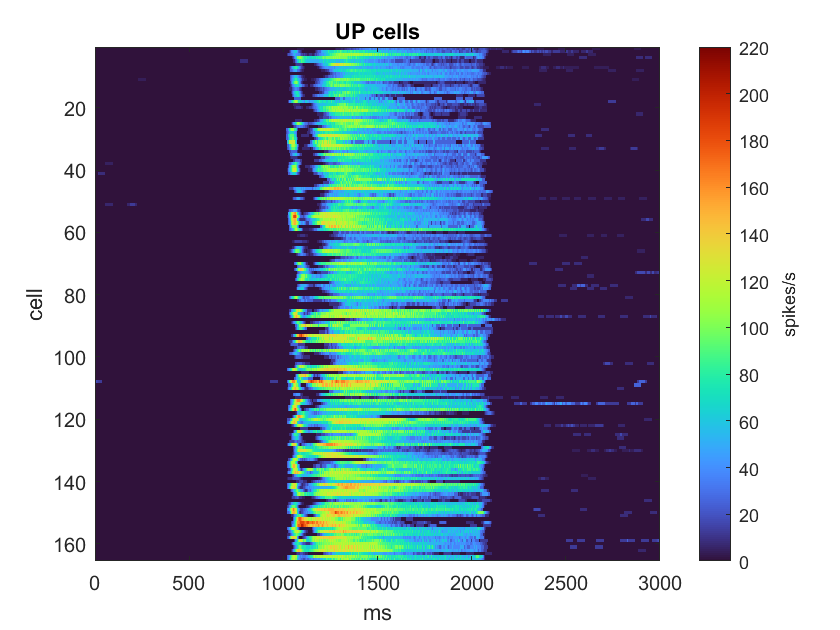

figure
imagesc(xvals, 1:size(upPSTH, 1), upPSTH)
hold on
caxis([0 220])
title('UP cells')
xlabel('ms')

ylabel('cell')
colormap(turbo)
h = colorbar;
ylabel(h, 'spikes/s')

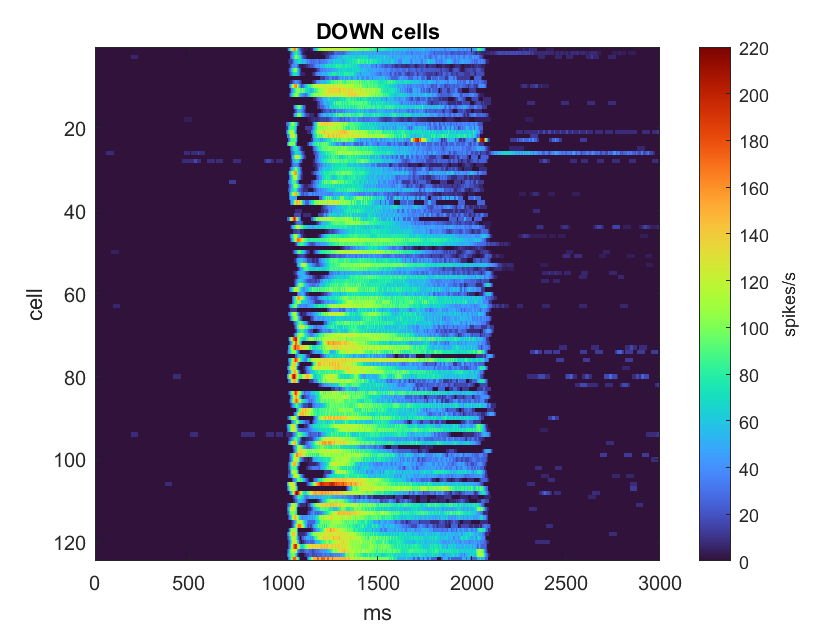

figure
imagesc(xvals, 1:size(downPSTH, 1), downPSTH)
hold on
caxis([0 220])
title('DOWN cells')
xlabel('ms')
ylabel('cell')
colormap(turbo)
h = colorbar;
ylabel(h, 'spikes/s')

## Total number of spikes

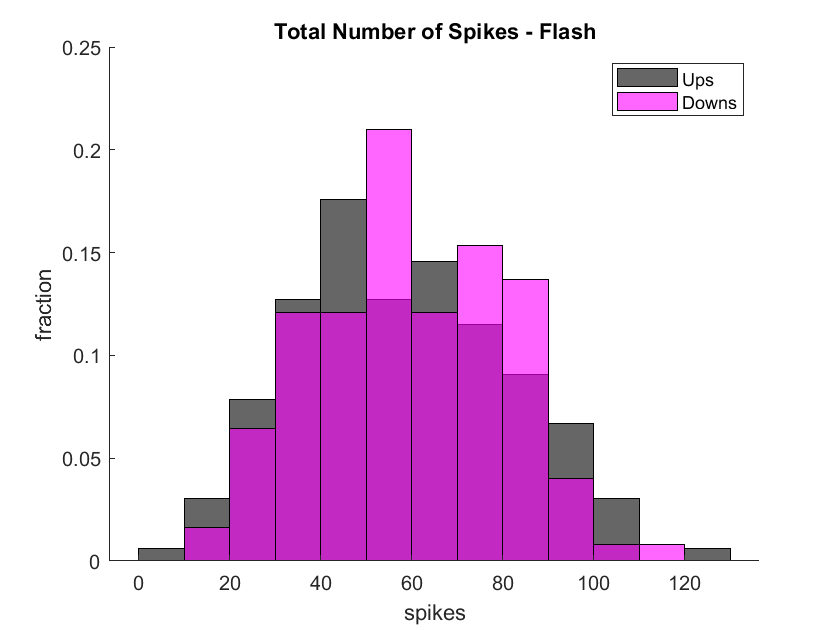

upTotalSpikes = trapz(upPSTH, 2)/(3000/stepSize)*3;
downTotalSpikes = trapz(downPSTH, 2)/(3000/stepSize)*3;

figure
h1 = histogram(upTotalSpikes, 'FaceColor', 'black', 'Normalization','probability');
hold on
h2 = histogram(downTotalSpikes, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization','probability');
h2.BinEdges = h1.BinEdges;
title('Total Number of Spikes - Flash')
xlabel('spikes')
ylabel('fraction')
legend('Ups', 'Downs')
box off

ranksum(upTotalSpikes, downTotalSpikes)

ans = 0.2985

## Max responses by cell type

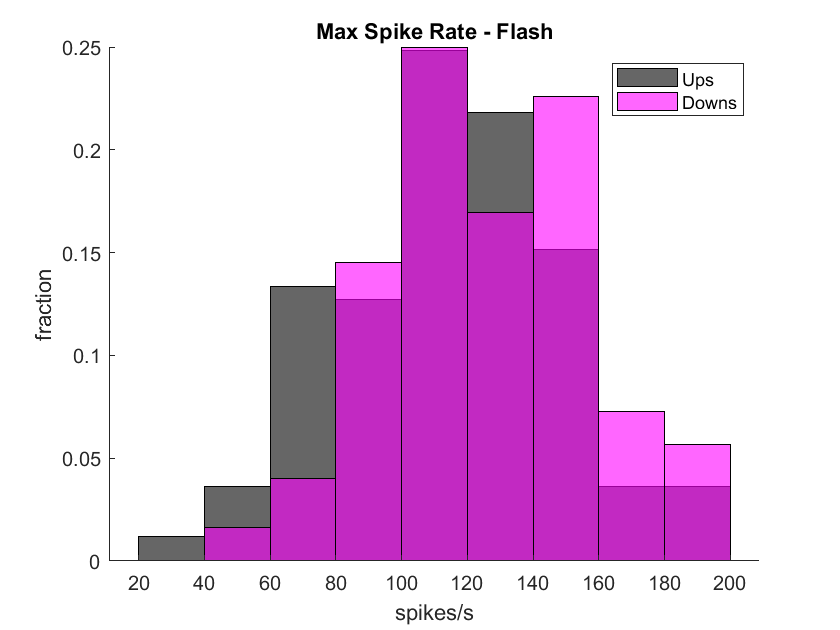

upMaxs = max(upPSTH, [], 2);
downMaxs = max(downPSTH, [], 2);

figure
h1 = histogram(upMaxs, 'FaceColor', 'black', 'Normalization','probability');
hold on
h2 = histogram(downMaxs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization','probability');
h2.BinEdges = h1.BinEdges;
title('Max Spike Rate - Flash')
xlabel('spikes/s')
ylabel('fraction')
legend('Ups', 'Downs')
box off

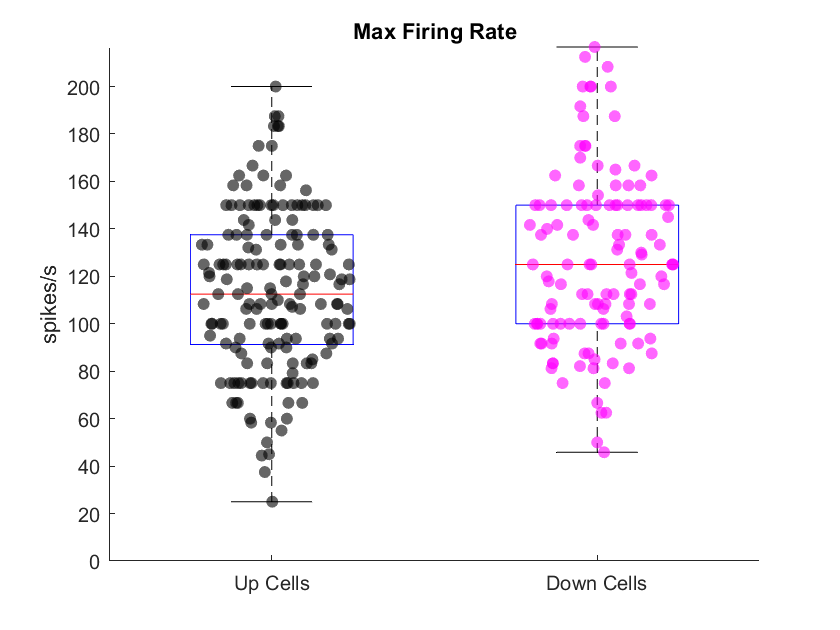

%box plot
groupIDs = zeros(1, numel([upMaxs; downMaxs]));
groupIDs(numel(upMaxs)+ 1:end) = 1;

allPoints = [upMaxs; downMaxs];

figure
title ('Max Firing Rate')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(upMaxs)), upMaxs,'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downMaxs))+1, downMaxs,'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 inf])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('spikes/s')
box off

disp(['p = ', num2str(ranksum(upMaxs, downMaxs))])

p = 0.0042466


## Average responses

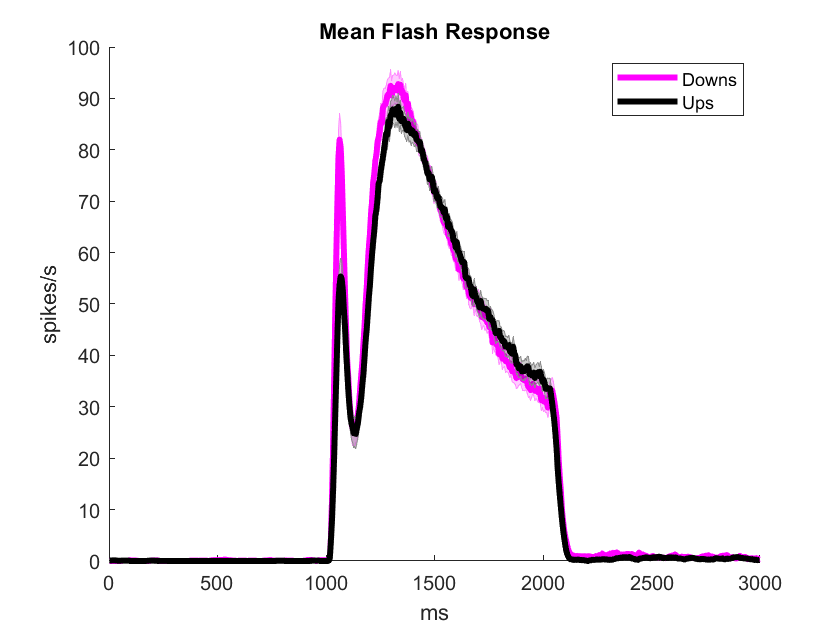

downAvg = mean(downPSTH);
upAvg = mean(upPSTH);
downSE = std(downPSTH)/sqrt(size(downPSTH, 1));
upSE = std(upPSTH)/sqrt(size(upPSTH, 1));

figure
shadedErrorBar(xvals, downAvg, downSE, 'lineprops', {'color', [255, 0, 255]/255, 'linewidth', 3})
hold on
shadedErrorBar(xvals, upAvg, upSE, 'lineprops', {'color', [0, 0, 0]/255, 'linewidth', 3})
title('Mean Flash Response')
legend('Downs', 'Ups')
xlabel('ms')
ylabel('spikes/s')
box off

## Average responses just in first 150 ms after flash

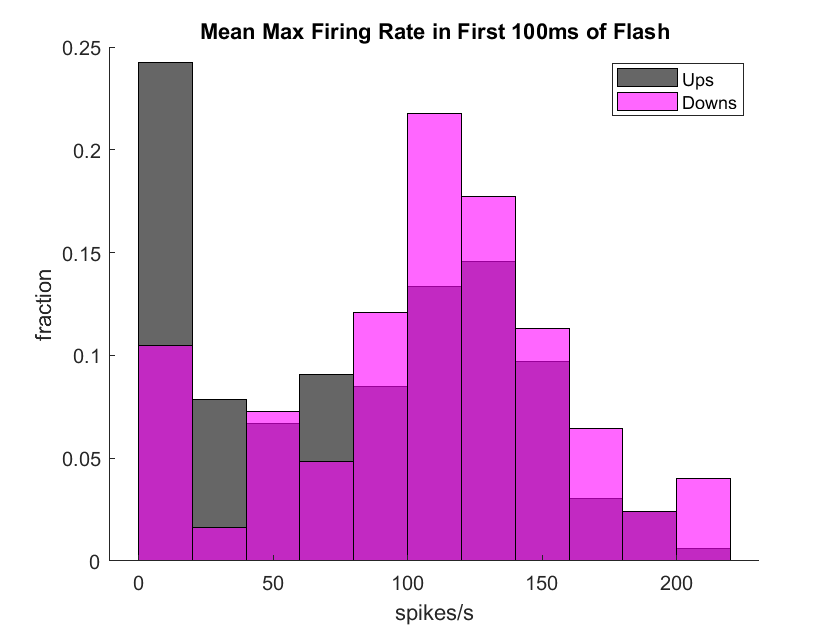

upFirst100ms = upPSTH(:, xvals>1000 & xvals < 1150);
downFirst100ms = downPSTH(:, xvals>1000 & xvals< 1150);

maxUpFirst100ms = max(upFirst100ms, [], 2);
maxDownFirst100ms = max(downFirst100ms, [],2);

%this next little bit will just sort the names of the UP and DOWN cells in
%order of their max firing rate in the first 100ms
[~, upOrder] = sort(maxUpFirst100ms);
[~, downOrder] = sort(maxDownFirst100ms);
upNamesSorted = upNames(upOrder);
downNamesSorted = downNames(downOrder);

figure
histogram(maxUpFirst100ms, 'BinEdges', 0:20:220, 'FaceColor', 'black', 'Normalization','probability')
hold on
histogram(maxDownFirst100ms, 'BinEdges', 0:20:220, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization','probability')
title('Mean Max Firing Rate in First 100ms of Flash')
legend('Ups', 'Downs')
xlabel('spikes/s')
ylabel('fraction')
box off

disp(['p = ', num2str(ranksum(maxUpFirst100ms, maxDownFirst100ms))])

p = 0.00013229


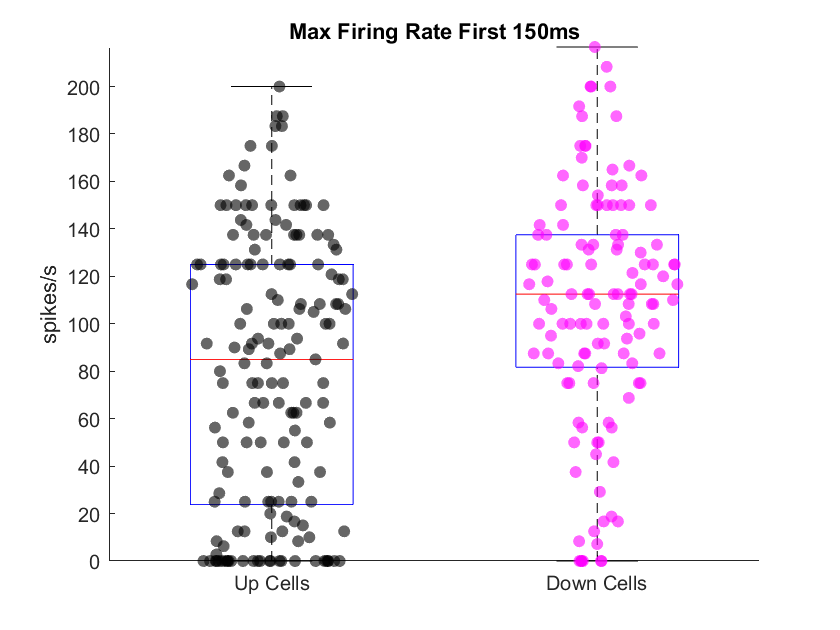

%box plot
groupIDs = zeros(1, numel([maxUpFirst100ms; maxDownFirst100ms]));
groupIDs(numel(maxUpFirst100ms)+ 1:end) = 1;

allPoints = [maxUpFirst100ms; maxDownFirst100ms];

figure
title ('Max Firing Rate First 150ms')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(maxUpFirst100ms)), maxUpFirst100ms,'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(maxDownFirst100ms))+1, maxDownFirst100ms,'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 inf])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('spikes/s')
box off

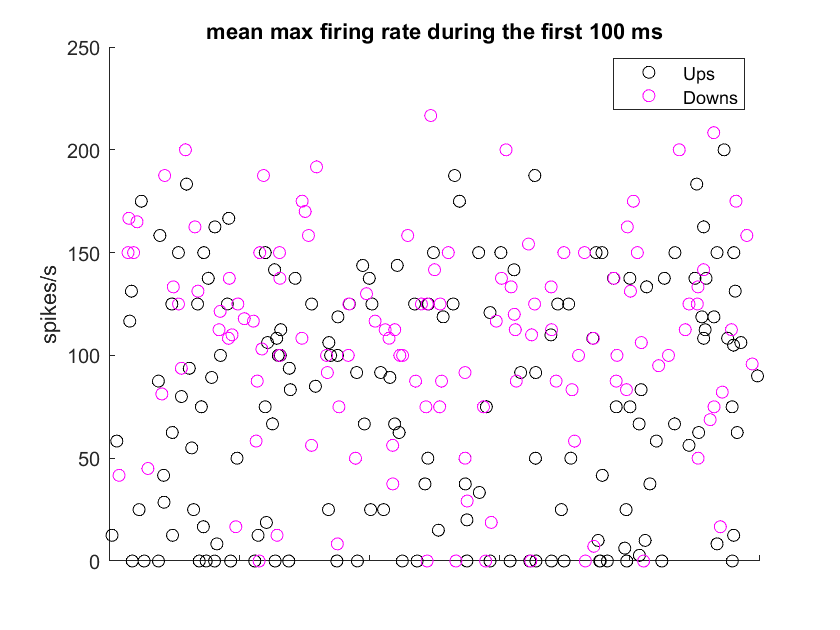


figure
scatter(rand(numel(maxUpFirst100ms), 1), maxUpFirst100ms, 'k')
hold on
scatter(rand(numel(maxDownFirst100ms), 1), maxDownFirst100ms, 'm')
title('mean max firing rate during the first 100 ms')
l = legend('Ups', 'Downs');
l.Location = 'best';
ylabel('spikes/s')
xticklabels({''})

## OFF response

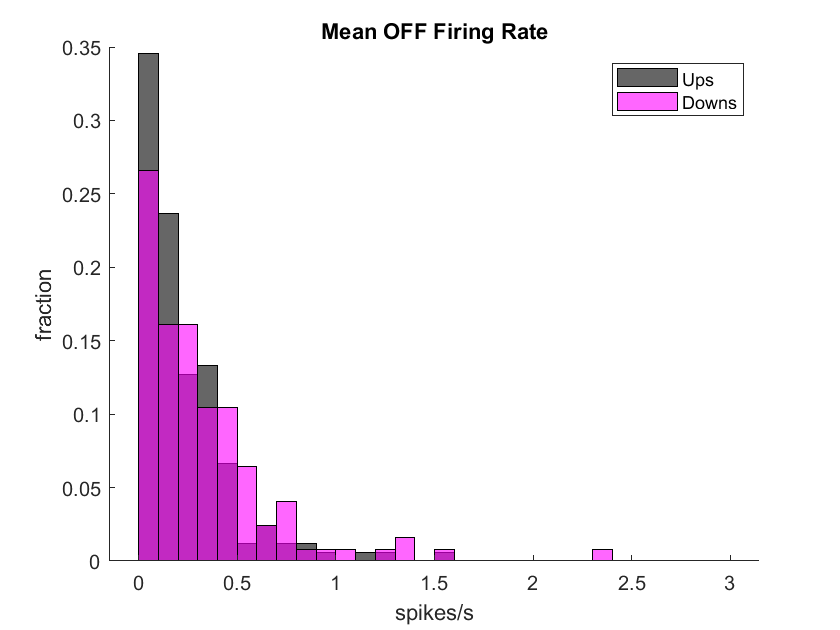

edgs = [0: 0.1: 3];
upNumOffSpikes = sum(upPSTH(:, xvals>2050), 2)/950;
downNumOffSpikes = sum(downPSTH(:, xvals>2050), 2)/950;
figure
h1 = histogram(upNumOffSpikes, 'BinEdges', edgs, 'FaceColor', 'black', 'Normalization', 'probability');
hold on
h2 = histogram(downNumOffSpikes,'BinEdges', edgs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinEdges = h1.BinEdges;
title('Mean OFF Firing Rate')
legend('Ups', 'Downs')
xlabel('spikes/s')
ylabel('fraction')
box off

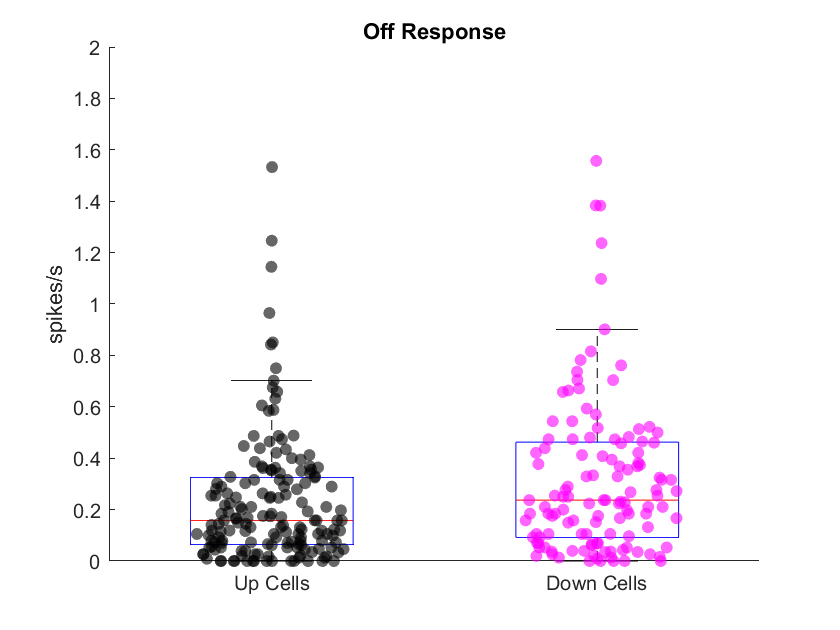

%box plot
groupIDs = zeros(1, numel([upNumOffSpikes; downNumOffSpikes]));
groupIDs(numel(upNumOffSpikes)+ 1:end) = 1;

allPoints = [upNumOffSpikes; downNumOffSpikes];

figure
title ('Off Response')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(upNumOffSpikes)), upNumOffSpikes,'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downNumOffSpikes))+1, downNumOffSpikes,'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 2])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('spikes/s')
box off


ranksum(downNumOffSpikes, upNumOffSpikes)

ans = 0.0067

## Pretime/baseline Firing rate

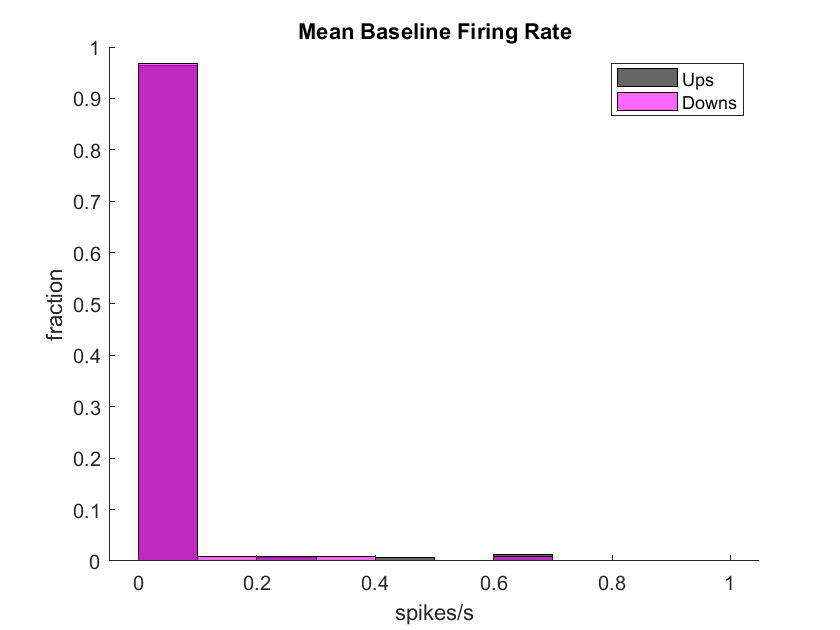

edgs = [0: 0.1: 1];
upPretimeSpikes = sum(upPSTH(:, xvals<1000), 2)/100;
downPretimeSpikes = sum(downPSTH(:, xvals<1000), 2)/1000;
figure
h1 = histogram(upPretimeSpikes, 'BinEdges', edgs, 'FaceColor', 'black', 'Normalization', 'probability');
hold on
h2 = histogram(downPretimeSpikes,'BinEdges', edgs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinEdges = h1.BinEdges;
title('Mean Baseline Firing Rate')
legend('Ups', 'Downs')
xlabel('spikes/s')
ylabel('fraction')
box off

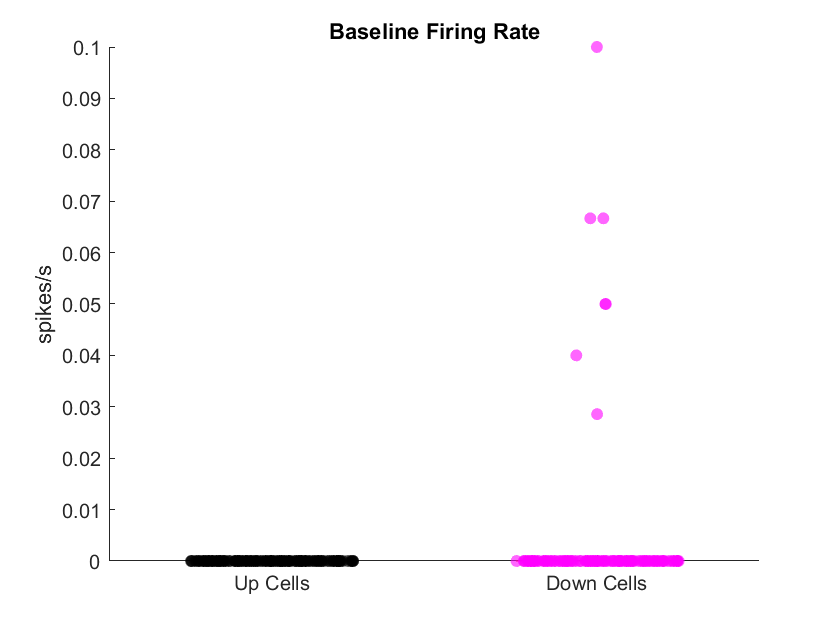

%box plot
groupIDs = zeros(1, numel([upPretimeSpikes; downPretimeSpikes]));
groupIDs(numel(upPretimeSpikes)+ 1:end) = 1;

allPoints = [upPretimeSpikes; downPretimeSpikes];

figure
title ('Baseline Firing Rate')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(upPretimeSpikes)), upPretimeSpikes,'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downPretimeSpikes))+1, downPretimeSpikes,'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 0.1])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('spikes/s')
box off


ranksum(downPretimeSpikes, upPretimeSpikes)

ans = 0.1268